# Sistemas Realimentados - 2023/1

## Nome: Arthur Lorencini Bergamaschi

## Data limite para entrega: 25/4

## Trabalho 2 - O método do lugar das raízes

I=2; % Seu valor de I
[g1,g3,g5]=init2(I);
datetime('now')

ans = datetime
   16-Apr-2023 12:48:17

**Atividade 1: Esboçar o lugar das raízes de 1+KG(s)=0 para K>0 e K<0. Desenhe à mão, usando as propriedades de construção do LR, digitalize e coloque abaixo. Incluir no esboço:**

1.1 Raizes para $K=0$ e $K\longrightarrow \infty$.

1.2 Pontos de passagem no eixo imaginário se houver.

1.3 As assintotas e seus ângulos.

1.4 Ponto de interseção das assíntotas

1.5 Localização dos pontos de raízes múltiplas (encontro de polos)

g1

g1 =
 
          2
  -----------------
  s^3 + 6 s^2 + 8 s
 
Continuous-time transfer function.
Model Properties


**Atividade 2: Seja o LR de 1+KG(s)=0 mostrado. Responder as perguntas abaixo, obtendo as informações aproximadas da figura:**

2.1 Quais são os polos e zeros de G(s)?

2.2 Quais são as raízes quando $K=0$ e $K\longrightarrow \infty$?

2.3 Para que valores de K esse sistema é estável?

2.4 Para que valores de K o par de polos complexos tem amortecimento $\zeta\geq0.707$?

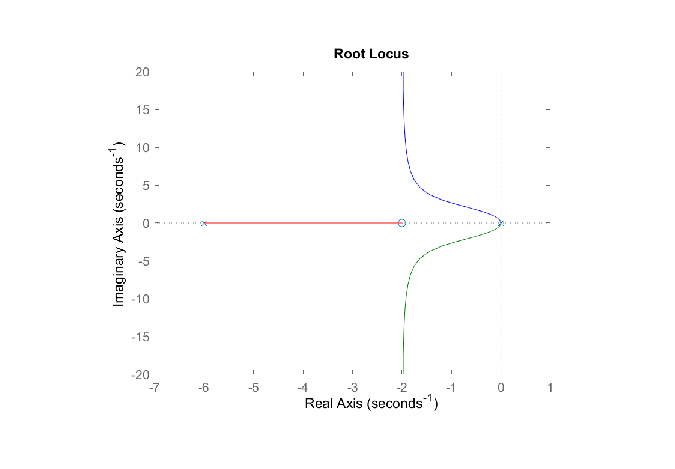

imshow('fig2.png')

- Um polo em -6, dois polos em 0. Há um zero em -2.

- a

- Para k > 0, o sistema é estável, pois todas as raízes vão se encontrar no lado esquerdo do eixo imaginário

sys = zpk([-2],[-6,0,0],1)

sys =
 
    (s+2)
  ---------
  s^2 (s+6)
 
Continuous-time zero/pole/gain model.
Model Properties


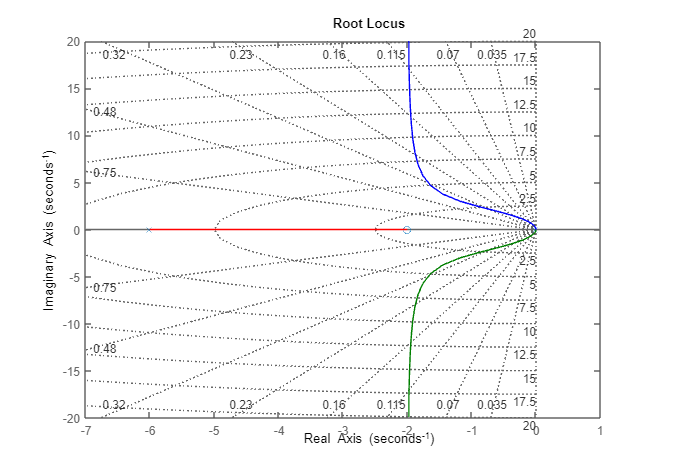

rlocus(sys)
sgrid

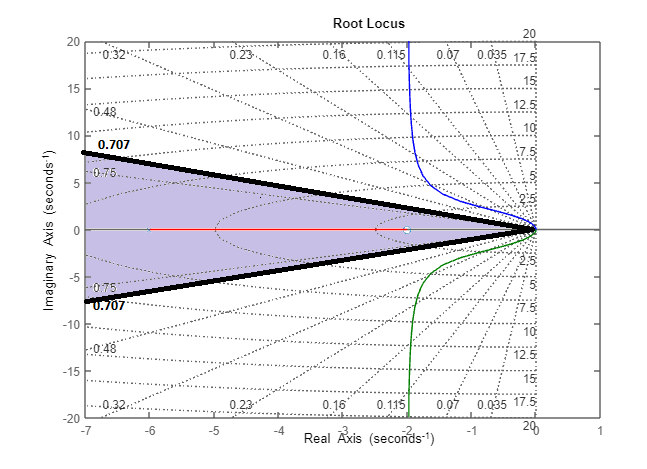

**Atividade 3: A figura mostra o lugar das raízes de 1+KG(s)=0 com as restrições de projeto em relação a sobreelevação e tempo de estabelecimento. Responder as perguntas abaixo:**

3.1 Para que valores de $K\in[-\infty, \infty]$este sistema é estável?

3.2 Para que valores de K $UP\leq10\%$?

3.3 Existem valores de K para os quais $t_s\leq \frac{5}{I}$s?

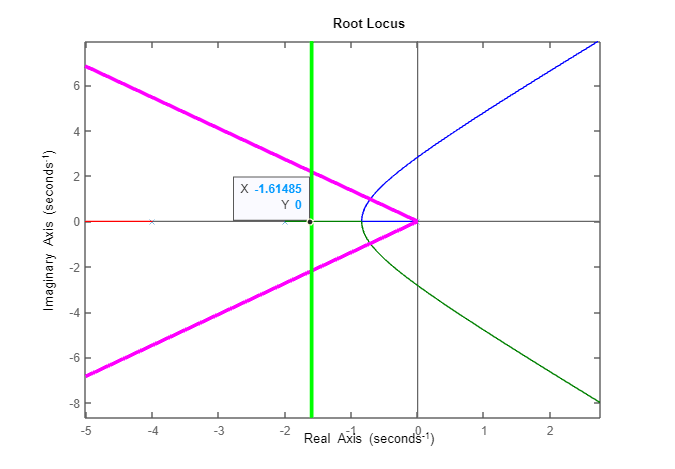

rlocus(g3)
hold on
xmin=-20; % Escolher xmin observando o LR (menor valor da parte real mostrada)
upts_no_lr(xmin,10,5/I);

Lembrando:  $\zeta =\cos \;\theta$ ,  $\mathrm{ts}=\frac{4}{\zeta \omega_n }$, $0<\zeta <0\ldotp 9$.

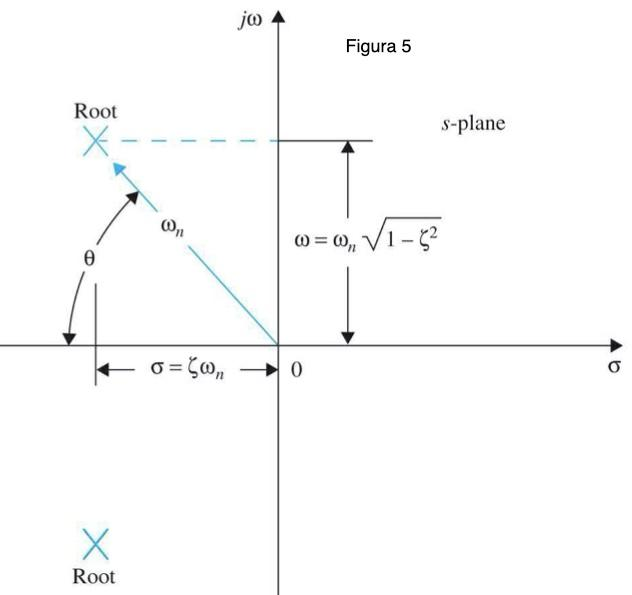

Resposta:

a. Utilizando o rlocus, podemos ver que 0 < k < 23.5. Pois o sistema terá polo que estará no semiplano esquerdo e no eixo imaginário. Claro que podemos ver o ponto e calcular tan-1(2.2/1.6) e ver os ângulos para as isolinhas de amortecimento.

b. Graficamente, podemos ver que para k < 3.3, o overshoot fica menor que 10%

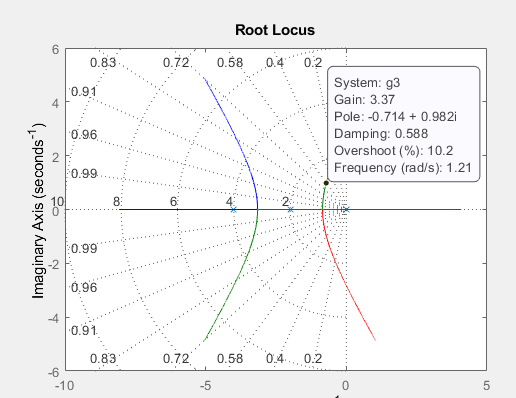

ts_max = 5/I

ts_max = 2.5000


$$\zeta \omega_n =\frac{4}{{\mathrm{ts}}_{\max } }=\frac{4}{2\ldotp 5}=1\ldotp 6=\mathrm{parte}\;\mathrm{real}\;\mathrm{do}\;\mathrm{polo}$$


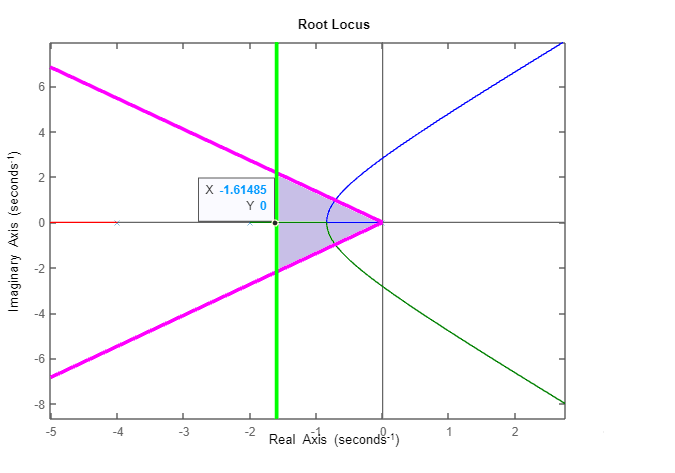

**Atividade 4: Seja o lugar das raízes mostrado. Explique o efeito da adição de um zero a este LR em diferentes localizações do eixo real, explicando que efeito haverá na resposta ao degrau. Use as propriedades do método do LR para explicar e justificar.**

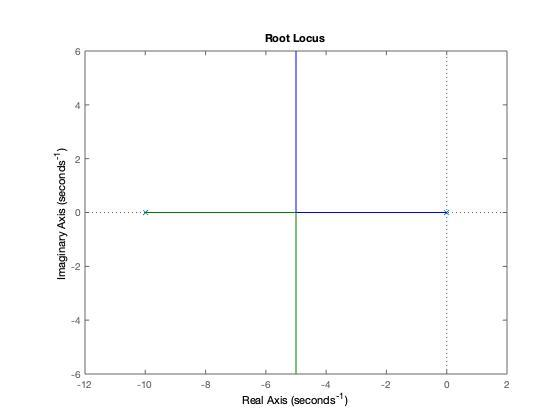

Para K>0

Em todos os casos, teremos apenas uma assíntota em 180º.

Ao adicionar um zero menor que -10, t

Ao adicionar um zero entre -10 e -5, todos as raízes estarão no eixo real.

Ao adicionar um zero entre -5 e 0,

Ao adicionar um zero maior que 0 

**Atividade 5: Seja o lugar das raízes de 1+KG(s)=0 mostrado.**

5.1 Ele foi desenhado para K>0 ou K<0? Explique.

5.2 Para que valores de $K\in[-\infty, \infty]$ este sistema é estável?

5.3 Para que valores de $K\in[-\infty, \infty]$ este sistema tem polos com parte real menor que $-I/4$?

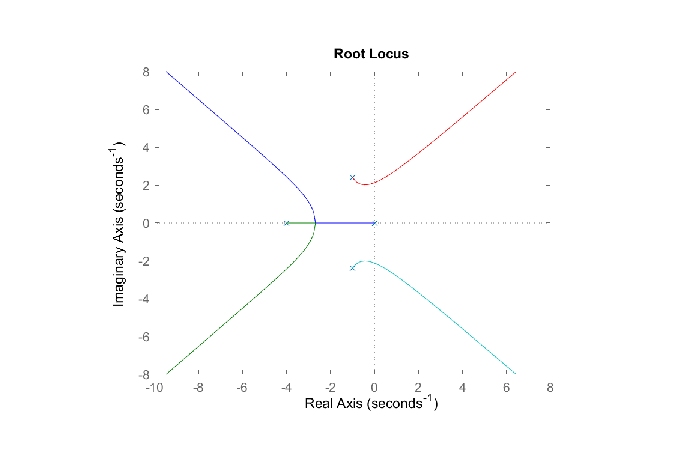

figure;
imshow('fig5.png');

**Atividade 6: Seja o diagrama de blocos mostrado. **

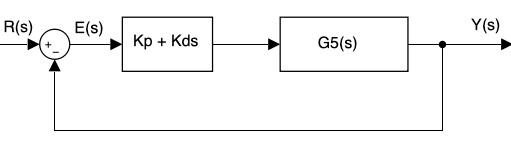

g5

g5 =
 
      2
  ---------
  s^2 + 7 s
 
Continuous-time transfer function.
Model Properties


6.1 Obtenha os valores de $K_p$ para os quais o erro à uma entrada rampa seja $\leq$1% **. **

6.2 Faça o LR para $K_d$ variando com $K_p$  fixo calculado no item 6.1. Escolher no LR um valor de $K_d$ que dê uma resposta rápida (ts pequeno) e pouco oscilatória ($\zeta$ grande).

6.3 Para mostrar que a escolha dos ganhos foi boa, simule g5(s) com o controlador $C(s)=K_p+K_ds$ para um degrau aplicado em R(s).